# Analysis Example

The methodology consists of four key steps, each requiring specific data points that are inputted at the beginning of the process. These data points are then used to convert the corporate targets into temperature scores at the company and the portfolio level.

**Step 1:** The targets are first filtered and if valid are each translated to a specific temperature, based on the relevant regression model. The sector classification of the company is used to ensure that the target is correctly mapped to the appropriate model e.g. a target for power generation must be mapped to the power sector pathway. This process enables the translation of target ambition over a certain target time period into a temperature score. For example, a 30% absolute reduction target over 10 years will be converted into a temperature score of 1.98°C.

**Step 2:** GHG emission data is employed to aggregate and target scores to produce a score at the company level.

**Step 3:** The company scores are combined with portfolio financial data to generate scores at the portfolio level.

**Step 4:** After the initial score calculations, a scenario generator can be used to determine how certain actions can change the temperature score. This can be done by changing your exposure to your holdings in the portfolio import file or by rerunning the calculations using

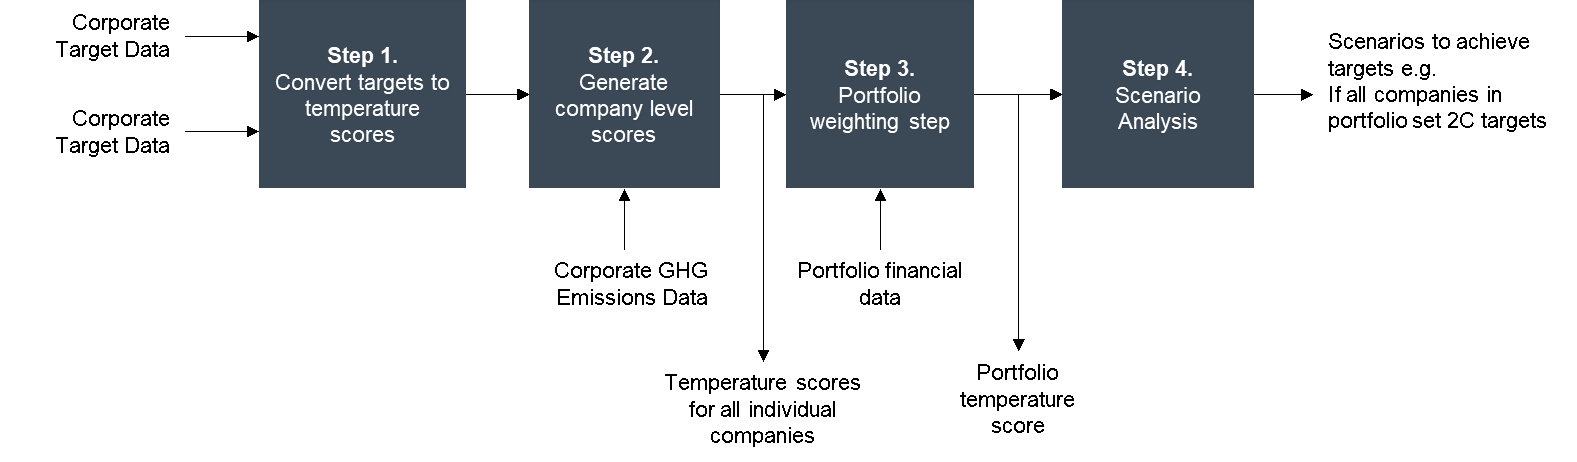

The methodology consists of four key steps, each requiring specific data points that are inputted at the beginning of the process. These data points are then used to convert the corporate targets into temperature scores at the company and the portfolio level.

**Step 1:** The targets are first filtered and if valid are each translated to a specific temperature, based on the relevant regression model. The sector classification of the company is used to ensure that the target is correctly mapped to the appropriate model e.g. a target for power generation must be mapped to the power sector pathway. This process enables the translation of target ambition over a certain target time period into a temperature score. For example, a 30% absolute reduction target over 10 years will be converted into a temperature score of 1.98°C.

**Step 2:** GHG emission data is employed to aggregate and target scores to produce a score at the company level.

**Step 3:** The company scores are combined with portfolio financial data to generate scores at the portfolio level.

**Step 4:** After the initial score calculations, a scenario generator can be used to determine how certain actions can change the temperature score. This can be done by changing your exposure to your holdings in the portfolio import file or by rerunning the calculations using

## Create a data provider

By running the following cell, you load our example data. If you want to score your own portfolio, this is where you can upload data from your data provider or your own data lake. Please refer to [Data Requirements](https://sciencebasedtargets.github.io/SBTi/DataRequirements.html#) for a full description of the data and formats needed.

By specifying a data provider, you can connect to the data source of your choice, e.g. CDP, Urgentem, your own data lake, etc. In this example, the provider data is located in an Excel file. Per default we use the example data downloaded in the previous step. To replace the example data with your own data, first place your file in the data folder:

- When using Google Colab: click the folder logo in the left pane; hover your mouse of the 'data' folder; click the three dots; click upload; select your file.

- When running this notebook locally: place your file in the 'data' folder that is located in the same directory as this notebook.

Next, change the file location between the quotes below: replace 'data_provider_example' with your_filename (don't remove the double quotes in the cell below).

dataProviderFile = fullfile(SBTiroot, 'examples', "data/data_provider_example.xlsx");
provider = SBTi.data.ExcelProvider(dataProviderFile);

## Load your portfolio

In this example, the portfolio data is stored as a CSV file. If you wish to replace the portfolio file with your own portfolio file, your CSV file should at least have a "company_id" column (the identifier of the company) and a "investment value" column (the amount of money invested in each of the companies in your portfolio e.g. the value of the shares you hold). Please refer to [Data Requirements](https://sciencebasedtargets.github.io/SBTi/DataRequirements.html#) for a full description of the data and formats needed. To change the portfolio file, follow the same steps as for the data provider, described above. Next, change the file location between the quotes below: replace '`example_portfolio`' with your_filename (don't remove the double quotes in the cell below).

examplePortfoliofile = fullfile(SBTiroot, 'examples', "data/example_portfolio.csv");
opts = detectImportOptions(examplePortfoliofile);
opts.Encoding = 'ISO-8859-15';
opts = setvartype(opts, 'engagement_target', 'logical');
portfolio = readtable(examplePortfoliofile, opts);
portfolio.engagement_target = logical(portfolio.engagement_target);
head(portfolio)

     company_name        company_id         company_isin       weights     investment_value    engagement_target
    ______________    ________________    ________________    _________    ________________    _________________

    {'Company AG'}    {'US0079031078'}    {'US0079031078'}    {'6.36%'}        35000000              true       
    {'Company AH'}    {'US00724F1012'}    {'US00724F1012'}    {'1.82%'}        10000000              false      
    {'Company AI'}    {'FR0000125338'}    {'FR0000125338'}    {'1.82%'}        10000000              false      
    {'Company AJ'}    {'US17275R1023'}    {'US17275R1023'}    {'1.82%'}        10000000              false      
    {'Company AK'}    {'CH0198251305'}    {'CH0198251305'}    {'1.82%'}        10000000              false      
    

To load the data from the data provider, we need to convert the data of the portfolio.

companies = SBTi.utils.table_to_portfolio(portfolio);

## Step 1 & 2: Aggregate multiple company targets to produce company score

The target protocol represents the first step of the process, which is to convert individual targets of various formats into temperature scores. This is achieved by generating simple regression models for estimated warming in 2100 from climate scenarios with short, medium, and long-term trends in metrics like absolute emissions or emissions intensities. Regression models are generated based on scenarios in the IPCC Special Report on [1.5°C scenario database](https://www.ipcc.ch/sr15/). In addition to defining methods for disclosed targets, this step outlines the methodology used to define a default score to be applied to all non-disclosing companies.

This stage will map the targets to the existing regression models, which uses the ISIC sector classification to link to target to the appropriate regression model. For example, a company in the power sector with an intensity target using a per MWh activity would be mapped to the power generation temperature pathway. The table below summarises the ISIC classifications and how the targets are mapped to regression models.

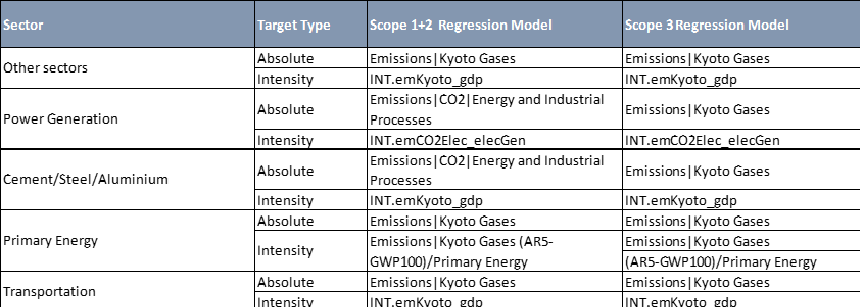

### How to convert a target to a temperature?

Since companies often have multiple climate targets, covering different scopes and timeframes, a protocol is then used to aggregate all target data into scores at a company level. This protocol defines the minimum quality criteria for determining the acceptability of a target to be scored and the steps required to identify and aggregate multiple targets to produce an overall company score. Scores are produced for both scope 1+2 and for scope 3, over 3 timeframes (short, mid, long-term). Hence the scope coverage and the target year of the targets is necessary to accurately classify these targets. The below figure shows how targets are currently split by scope and timeframe.

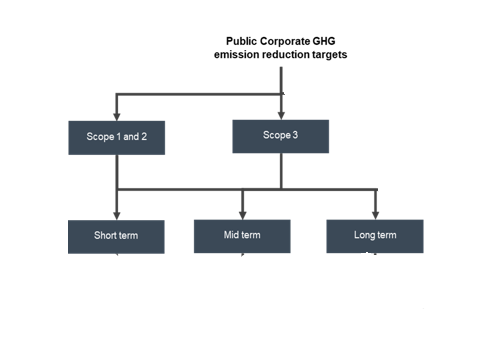

### Scope Classification

The targets are first sorted by scope. The table below provides examples of how these targets are classified into either scope 1+2 or scope 3. For combined targets (scope 1+2+3) where the underlying composition is not clear (i.e. the % scope coverage), the ambition is applied only to the scope 1+2 portion, and the if no details on scope 3 coverage are provided, the scope 3 portion would receive the default score.

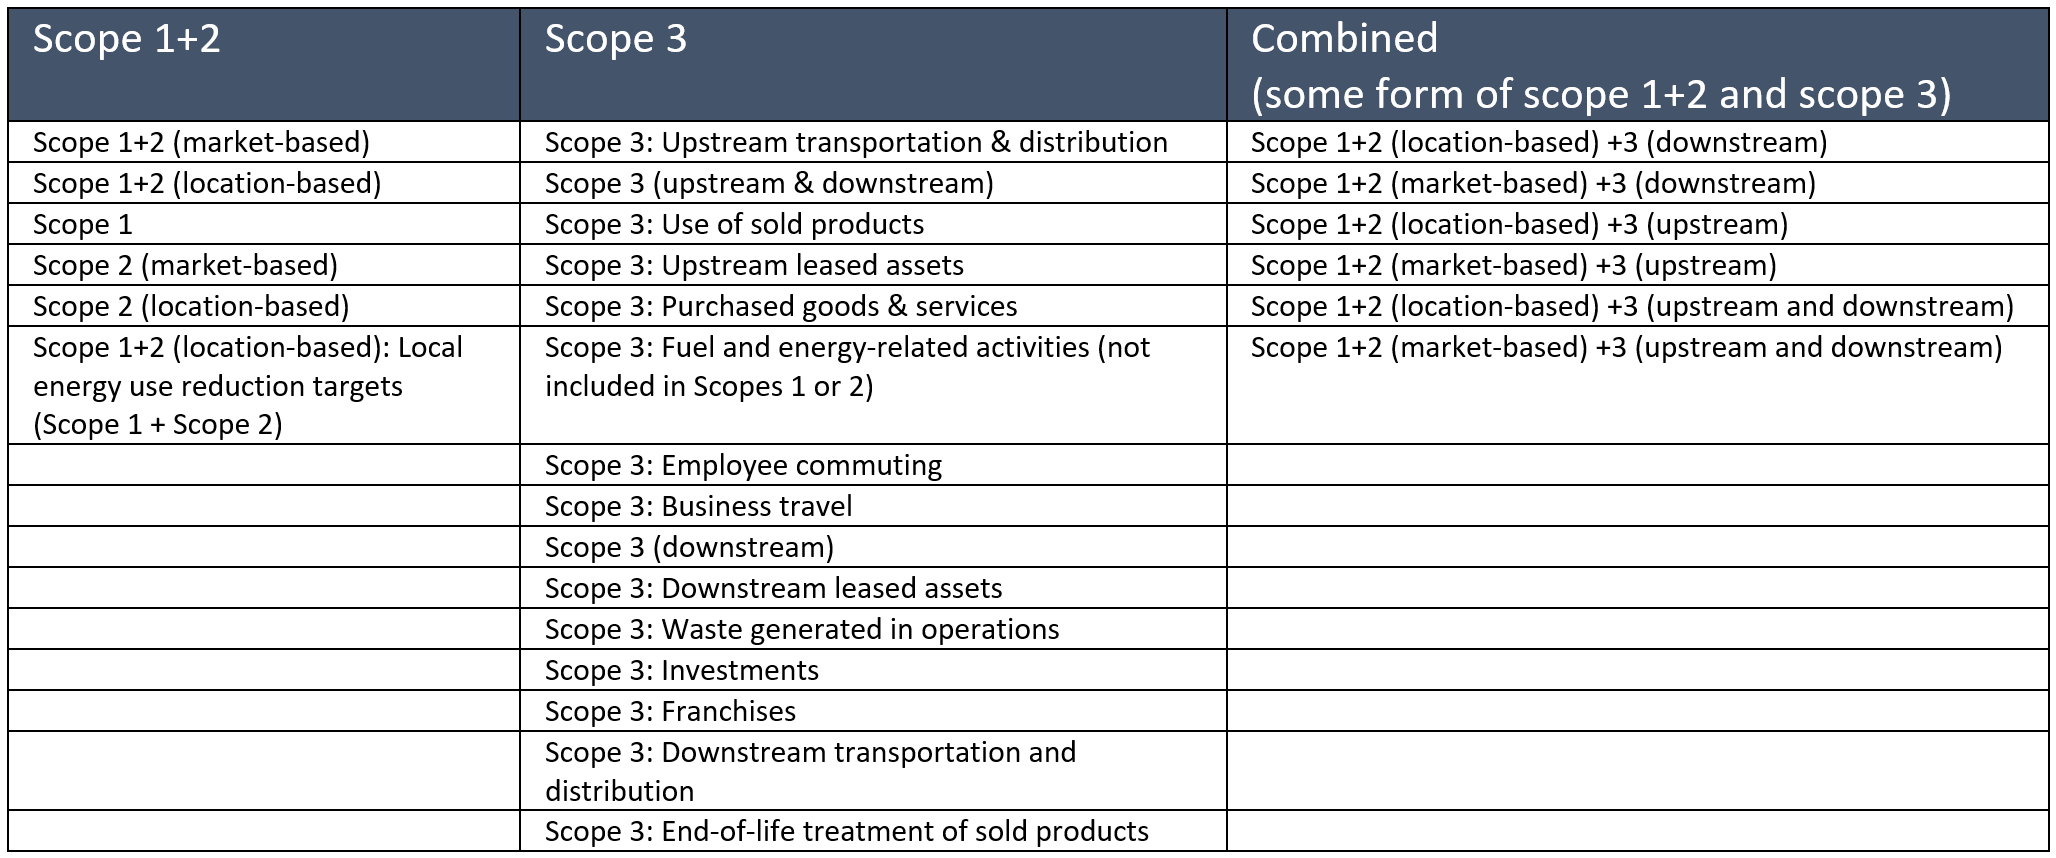

### Timeframe

The targets are the sorted by timeframe.

- SHORT: targets shorter than 5 years

- MID: targets between 5 and 15 years

- LONG: targets longer than 15 years

### Scope Coverage

The scope coverage determines the amount of emissions in the scope that are covered by the target. For scope 1+2 targets, all targets that are greater than 95% coverage are valid, no further revision needs to be undertaken. The ambition of the target is however, normalised to the relative boundary coverage of the target. For all scope 1+2 targets under 95% coverage, and scope 3 targets under 67% coverage, the ambition of the target is therefore linked to the coverage. This means an ambitious target covering only a small portion of the scope emissions would be weighted lower as a result of the reduced coverage. The temperature score for the scope is computed using the following equation, where TS is temperature score:

`Scope TS = (% emissions in scope covered by target) x (target TS)`

### Company Temperature Scores

One representative score is produced for each of the following six options, displayed in the table below.

In cases where more than one target is disclosed for a given scope, or timeframe e.g. two midterm targets covering scope 1+2, multiple scores per category would be produced. To generate just one representative score per category, a series of filtering steps is performed:

For all companies with one valid target in each scope and timeframe, generate the 6 scores per company. For companies who do not report, for example a scope 3 target, they receive a default score. For companies with no valid targets, all 6 entries would receive default score (see below). The 6 entries are combined to produce an overall scope 1+2+3 score using the most recent reported GHG weighting of the company.

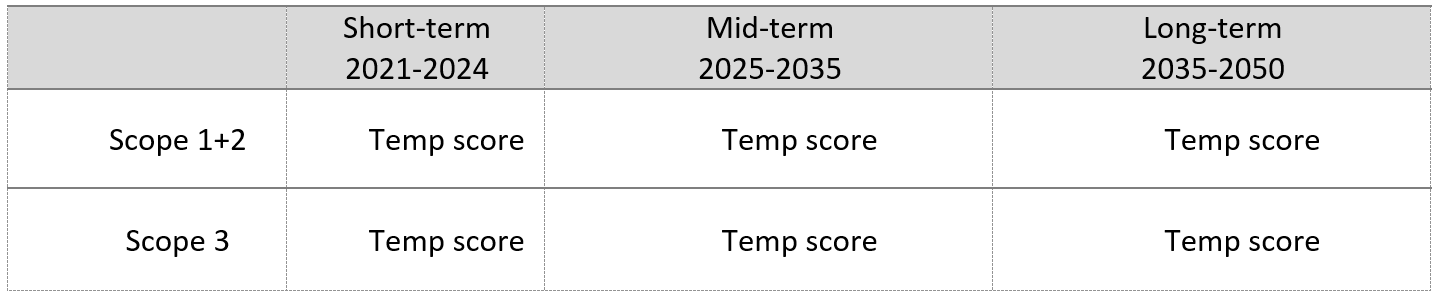

### Default Score

For companies who do not have valid targets, or if they do not have sufficient information covering a particular scope or timeframe, a default score is applied. The temperature rating methodology will use a 3.2°C value as an interim solution to derive temperature scores for companies with no forward-looking targets. This implies that these companies are expected to decarbonise along a 3.2°C pathway, consistent with global policies implemented to ensure reduction of emissions at this rate. The tool enables users to choose their own default score at the following temperatures: 3.2°C, 3.9°C or 4.5°C.

### Calculate the company temperature scores

The temperature score is calculated via the following steps:

- Target validation protocol: Here all targets are sorted by time frame and scope per company. For each combination a 'best' target is chosen.

- Mapping: Each target is mapped to a regression model based on the type of target (absolute vs. intensity), the company ISIC, the intensity metric (for intensity based targets) and the scope.

- Calculation: The mapped regression model returns a linear function to calculate the temperature score based on the linear annual reduction (LAR) of the ambition. TS = intersect + slope * LAR. For example, the formula of the Kyoto Gases regression is TS = 2.7 + (-0.31) * LAR.

In the amended portfolio you'll find your original portfolio, amended with the emissions and the temperature score.

The temperature scores can be computed for different scopes and different timeframes. More information on scopes and timeframes can be found on the SBTi website.

The timeframe options are SHORT, MID and LONG-term and can be implemented through the ETimeFrames object, in the code below. For example, you can add the SHORT timeframe by replacing the first line of the following cell by: `time_frames = [ETimeFrames.SHORT, ETimeFrames.MID]`

The scope options are S1S2, S3 and S1S2S3 and can be implemented using the EScope object. For example, you can add the S3 scope by replacing the second line of the following cell by: `scopes = [EScope.S1S2, EScope.S3, EScope.S1S2S3]`

- S1: scope 1

- S2: scope 2

- S2: scope 3

Finally, the default temperature score can be specified by assigning the value 3.2, 3.9 or 4.5 on the third line in the following cell.

In this example, we use the mid-term timeframe and the S1S2 & S1S2S3 scopes to calculate the aggregated company temperature scores. The default temperature score is 3.2.

import SBTi.*
time_frames = ETimeFrames.MID;
scopes = [EScope.S1S2, EScope.S1S2S3];
fallback_score = 3.2;
temperature_score = SBTi.TemperatureScore( time_frames=time_frames, scopes=scopes, fallback_score=fallback_score);
amended_portfolio = temperature_score.calculate(data_providers=provider, portfolio=companies);

      company_id      time_frame     scope     achieved_reduction    base_year    base_year_ghg_s1    base_year_ghg_s2    base_year_ghg_s3    coverage_s1    coverage_s2    coverage_s3    end_year    intensity_metric    reduction_ambition    start_year    target_type    company_name      isic           ghg_s1s2             ghg_s3           country           region                  sector             industry_level_1    industry_level_2    industry_level_3    industry_level_4    company_revenue     company_market

head(amended_portfolio)

## Step 3: Calculate a portfolio level temperature score

This step generates the results at the portfolio level for both the portfolio coverage and the temperature scoring method. Seven portfolio weighting options currently exist:

- Option 1: Weighted average temperature score (WATS)

- Option 2: Total emissions weighted temperature score (TETS)

- Option 3: Market Owned emissions weighted temperature score (MOTS)

- Option 4: Enterprise Owned emissions weighted temperature score (EOTS).

- Option 5: EV + Cash emissions weighted temperature score (ECOTS)

- Option 6: Total Assets emissions weighted temperature score (AOTS)

- Option 7: Revenue owned emissions weighted temperature score (ROTS)

Please see Section 3 of the [temperature scoring methodology](https://sciencebasedtargets.org/wp-content/uploads/2020/09/Temperature-Rating-Methodology-V1.pdf) for further details of the weighting calculation steps.

The financial information imported through the in the data_provider_example.xlxs at the start of this process is used to weight the individual companies in a portfolio. For example, the EOTS, uses the portfolio invested value as a portion of the company’s enterprise value to weight the company’s temperature score. The scores at the company level are aggregated for both scope 1+2, and for scope 1+2+3, generating two portfolio scores for the selected time period.

For analysing SBT Portfolio Coverage, the tool also displays the percentage of SBTi approved companies on the portfolio based on the same weighting approach.

In this example we use the "Weighted Average Temperature Score". For more details on how to use the various weighting options in the notebook, have a look at notebook 3 ("3_portfolio_aggregations.ipynb" in the examples folder in [GitHub](https://github.com/ScienceBasedTargets/SBTi-finance-tool)). The temperature scores are calculated per time-frame/scope combination.

To change the aggregation method, replace the extension "`WATS`" in `PortfolioAggregationMethod.WATS` (the first line) with the abbreviation of the desired aggregation method, e.g. ECOTS, from the list of aggregation options above. The output displays the portfolio temperature score for the time frame and the scopes you have selected.

temperature_score.aggregation_method = SBTi.PortfolioAggregationMethod.ROTS;
aggregated_portfolio = temperature_score.aggregate_scores(amended_portfolio);
SBTi.utils.print_aggregations(aggregated_portfolio)

 Timeframe      Scope    Temp score
       mid       S1S2       3.12
       mid     S1S2S3       2.73


### Portfolio coverage

The portfolio coverage gives insights in the coverage of portfolio entities that have set GHG emissions reduction targets, STBi-validated or otherwise. Companies with SBTi status Approved have a score of 100%, all others have a score of 0%. The aggregation method used for the portfolio coverage is the same as for the temperature score. If you want to change that you can do so in the previous section.

portfolio_coverage_tvp = SBTi.PortfolioCoverageTVP();
coverage = portfolio_coverage_tvp.get_portfolio_coverage(amended_portfolio, temperature_score.aggregation_method);
fprintf("Part of portfolio with climate targets is %.2f%%",coverage)

Part of portfolio with climate targets is 24.10%

## Step 4: How can I improve my portfolio's temperature score?

The final step can be used to get insight into the effect your action can have on your temperature score. This can be done by first analysing for example the current hotspots and contributors to the portfolio and sector TS (temperature score).

Finally you can also model changes the impact of changes in exposure of your holdings in the portfolio by rerunning the calculations using various scenarios. These scenarios give you an insight to how your score will be affected by certain engagement actions.

A total of 6 ready made scenarios can be employed to test strategies for reducing the current temperature score in the last example of this section.

### Analysing hotspots

The first analysis of your portfolio could be to understand if you have any particular hotspots in your portfolio. We can do that by analysing different groupings of companies.

The tool allows you to calculate temperature scores for *groups* of companies. In this example we group the scores by sector and region, and leave the timeframe and scope unchanged. Any categorical variable in the data provided by you or your data provider (in the `Data_Provider_Example.xlsx` imported above) can be used as grouping variable, e.g. sectors, industries, regions, countries, market cap buckets, as well as the additional fields you imported via the portfolio data.

You can change the variable by which the data is grouped by replacing the fourth line in the following cell. For example, replacing "grouping=['sector', 'region']" by "grouping=['sector', 'country']" would result in temperature scores per sector per country. If you want to change the time frame as well, please refer to the section 'Calculate the company temperature scores' above.

grouping = ["sector", "region"];
temperature_score = SBTi.TemperatureScore( time_frames=time_frames, scopes=scopes, grouping=grouping );
grouped_portfolio = temperature_score.calculate(data_providers=provider, portfolio=companies)

grouped_portfolio = 49×47 table
      company_id      time_frame     scope     achieved_reduction    base_year    base_year_ghg_s1    base_year_ghg_s2    base_year_ghg_s3    coverage_s1    coverage_s2    coverage_s3    end_year    intensity_metric    reduction_ambition    start_year    target_type    company_name      isic           ghg_s1s2             ghg_s3            country           region                  sector             industry_level_1    industry_level_2    industry_level_3    industry_level_4    company_revenue

grouped_aggregations = temperature_score.aggregate_scores(grouped_portfolio);

The aggregated scores can then be used, for example, to show the relation between sectors and regions with respect to temperature score. A visualization of this relation is shown in the heatmap below. The grey fields indicate that the portfolio contains no assest for those combinations.

#### Quick analysis

We can see here that our North American (NA) Health Care, Asian Consumer discretionary, and NA and Asian IT are in reasonable shape, but that we have many sectors across the globe that have a large number of companies with default scores, where we need to engage and influence these companies to set targets. We need to run some more detailed analysis to identify which sectors and companies are the best candidates for our engagement.

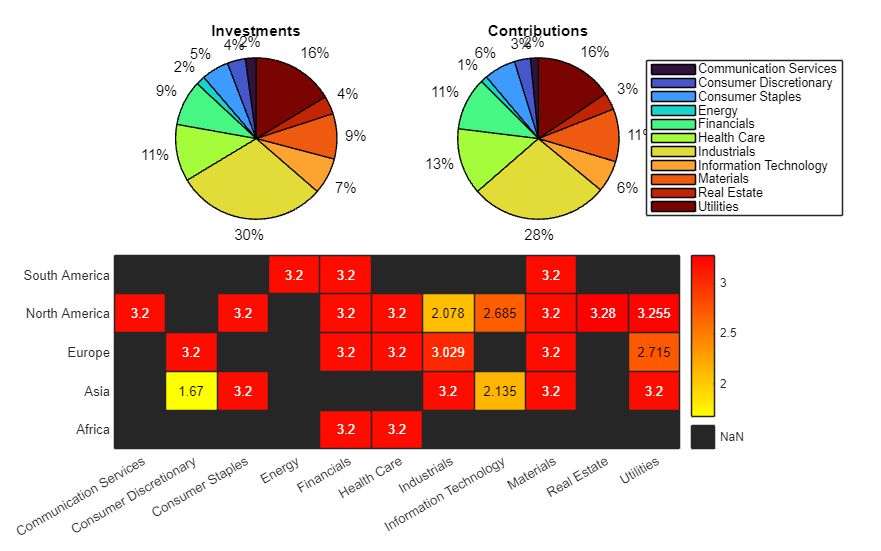

analysis_parameters = {ETimeFrames.MID, EScope.S1S2, grouping};
SBTi.utils.plot_grouped_heatmap(grouped_aggregations, analysis_parameters{:});

For example, we see that the Industrials in Asia perform worse than their counterparts in North America and Europe. We can zoom in on the companies in this group and their relative contributions to the group's temperature score.

region =  "Asia";
sector = "Industrials";
group = sector + '-' + region;
group_contributions = SBTi.utils.get_contributions_per_group(grouped_aggregations, analysis_parameters, group)

group_contributions = 3×5 table
          group           company_name      company_id      temperature_score    contribution_relative
    __________________    ____________    ______________    _________________    _____________________

    "Industrials-Asia"    "Company G"     "CN0000000007"           3.2             33.3333333333333   
    "Industrials-Asia"    "Company AS"    "JP3401400001"           3.2             33.3333333333333   
    "Industrials-Asia"    "Company AE"    "TH0000000031"           3.2             33.3333333333333   


### Sector analysis

Sector analysis may help us with bringing some clarity into our analysis from the heatmap above. In order to identify the companies that your portfolio would most benefit from engaging with, we can start with identifying the biggest contributing sectors to the portfolio's temperature score, as in our example below.

Contributions can be identified on an individual company level, as well as contributions from companies grouped by one of their characteristics, e.g. sector or region. The exact definitions of companies' contributions to the portfolio temperature scores depend on the selected aggregation method.

You can group companies on any categorical variable (e.g. sectors, countries, market cap buckets, investment strategies, etc) you provide through your dataprovider, in this example in the Data_Provider_Example.xlsx imported above.

For our analysis we select one time-frame (MID) and one scope (S1+S2) and group the outcomes on sector and compare AUM to temperature score contribution. We also then display the sector temperature scores.

To change the time frame, replace the extension "MID" in ETimeFrames.MID (the first line) to SHORT or LONG. To change the time frame, replace the extension "S1S2" in EScope.S1S2 (the second line) to S3 or S1S2S3. To change the grouping, replace 'sector' (the third line) to the category variable you are interested in.

#### Quick analysis

In this example we can see that Materials, Financials, Energy, Consumer Staples and the Communication sectors are all scoring above 3.0C. From the pie charts we can also see that Materials, Financials and Consumer Staples are contributing more to the temperature score than their weight in the portfolio.

time_frames = SBTi.ETimeFrames.MID;
scopes = SBTi.EScope.S1S2;
grouping = "sector";
analysis_parameters = {time_frames, scopes, grouping};
temperature_score = SBTi.TemperatureScore(time_frames=time_frames, scopes=scopes, grouping=grouping);
amended_portfolio = temperature_score.calculate(data_providers=provider, portfolio=companies);
aggregated_portfolio = temperature_score.aggregate_scores(amended_portfolio);
company_contributions = SBTi.utils.collect_company_contributions(aggregated_portfolio, amended_portfolio, analysis_parameters)

company_contributions = 49×10 table
    company_name      contribution      temperature_score    company_name_right      company_id      company_market_cap    investment_value             sector             portfolio_percentage    ownership_percentage
    ____________    ________________    _________________    __________________    ______________    __________________    ________________    ________________________    ____________________    ____________________

    "Company N"     8.59060402684564           3.2              "Company N"        "FR0000000014"     22740883934.2523         43000000        "Health Care"                 7.81818181818182  

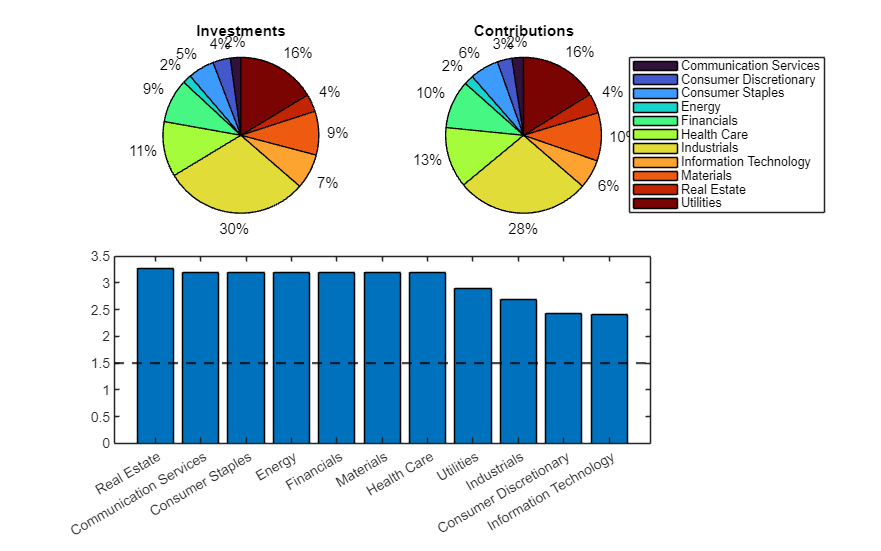

SBTi.utils.plot_grouped_statistics(aggregated_portfolio, company_contributions, analysis_parameters)

We can use what we learned from this analysis to drill into a few of the highest contributing scoring sectors to see which companies are the biggest contributors on the sector level. Considering the health care sector, for instance, we see in the table below that Company N is by far the largest contributor, and might therefore be a candidate to engage with.

sector_contributions = company_contributions(:,["company_name", "company_id", "sector", "contribution", "temperature_score", "ownership_percentage", "portfolio_percentage"]);
sector_contributions(sector_contributions.sector == 'Health Care', :)

ans = 3×7 table
    company_name      company_id         sector          contribution      temperature_score    ownership_percentage    portfolio_percentage
    ____________    ______________    _____________    ________________    _________________    ____________________    ____________________

    "Company N"     "FR0000000014"    "Health Care"    8.59060402684564           3.2             0.189086757244442       7.81818181818182  
    "Company AD"    "KE0000000030"    "Health Care"     1.9978148899641           3.2            0.0132429163854911       1.81818181818182  
    "Company AL"    "US1266501006"    "Health Care"     1.9978148899641           3.2            0.0111746981917322       1.81818181818182  


### Companies to engage with

In addition to statistics of the companies grouped by a given category, as we did with the sector analysis above, you can analyse the companies' individual contributions to the portfolio temperature score across the whole portfolio, as we have done below. Alternatively we can use the information we gathered above to do the below analysis for one of the identified sectors. To reiterate, the contribution column shows the contribution of a specific company to the overall portfolio temperature score. The computation of these contributions differs, in accordance with the aggregation methods explained above.

In this analysis we are also choosing to display temperature score, ownership and portfolio weight. Therefore, we can use this table to analyse which companies we may have a better chance of having a successful engagement with. We show the top 10 contributing companies. To see more or fewer companies change the '10' near the end of the line in "[:10]".Quick analysis

In this case we are primarily looking at our ownership of the company in relation to the contribution to find companies which we may be able to influence and where our work will have an impact on our portfolio TS.

Company N has the biggest contribution to our TS, and even if we have a substantial position in our portfolio, we own a very small part of the company, so any engagement effort by just us may not be that successsful.

We may have better luck with Company Q where we own close to 5% of the company, and it is still a reasonably large position in our portfolio and if we are successful, it may have a bigger impact on our portfolio score than with for example company N.

Naturally, we can join other investors to influence Company N to convince them to set emission reduction targets. This contribution table gives you some of the information you need to make these decisions.

head(company_contributions(:,["company_name", "company_id", "contribution", "temperature_score", "ownership_percentage", "portfolio_percentage"]))

    company_name      company_id        contribution      temperature_score    ownership_percentage    portfolio_percentage
    ____________    ______________    ________________    _________________    ____________________    ____________________

    "Company N"     "FR0000000014"    8.59060402684564           3.2             0.189086757244442       7.81818181818182  
    "Company AG"    "US0079031078"    4.43577337287342          2.03             0.334454372652329       6.36363636363636  
    "Company Q"     "CA0000000017"    2.39737786795692           3.2              4.81112140907686       2.18181818181818  
    "Company AO"    "TW0002308004"    2.39113469642578          3.83             0.014135091426861       1.81818181818182  
    "Company U"     "US0000000021"    2.09770563446

### What-if analysis

To determine the effect of engaging (part of) your portfolio, you can run a number of scenarios:

- 1: Engage companies to set 2 degree targets. This means that the score of all companies that didn't yet set a target will be set to 2 degrees Celsius.

- 2: Engage companies to set well below 2 degree targets. The maximum score for all companies that have set targets will be capped at 1.75 degrees Celsius.

- 3a: Engage the top 10 contributors to set 2 degree targets.

- 3b: Engage the top 10 contributors to have set well below 2 degree targets. This means that the maximum score for all the targets of these companies will be capped at 1.75 degrees Celsius.

- 4a: Engage the predefined companies to set 2 degree targets.

- 4b: Engage the predefined companies to set well below 2 degree targets. This means that the maximum score for all the targets of these companies will be capped at 1.75 degrees Celsius.

In this example, we identified a couple of companies above where we think we can have some success in our engagement efforts. Next, we will therefore investigate the effect of engaging Company Q and Company AM in setting targets.

The cell below defines scenario 4a, which means that we manage to get the companies we engage with, to set GHG emission reduction targets that give them both a score of 2.0C. We will define the companies in the next cell below. To change the scenario, replace the extension "HIGHEST_CONTRIBUTORS_APPROVED" in ScenarioType.HIGHEST_CONTRIBUTORS_APPROVED (the second line) to TARGETS (for scenario 1), APPROVED_TARGETS (scenario 2) or HIGHEST_CONTRIBUTORS (scenario 3). To differentiate between options a and b in scenario 3 and 4, change the extension "SET_TARGETS" in EngagementType.SET_TARGETS. Use "SET_TARGETS" for option a and "SET_SBTI_TARGETS" for option b. For scenarios 1 and 2 the choice here does not matter. In the fourth and fifth lines the aggregation method and grouping are specified. You can change these the same way as in the previous sections.

scenario = SBTi.Scenario();
scenario.scenario_type = SBTi.ScenarioType.HIGHEST_CONTRIBUTORS_APPROVED;
scenario.engagement_type = SBTi.EngagementType.SET_TARGETS;

### Portfolio temperature score impact

In our what-if analysis, we can now add Company Q and Company AM with company IDs CA0000000017 and FR0000120644 to to the companies which have set a target. Please note that our example portfolio file contains a column named "engagement_target". The companies with values of 1.0 in this column are included in this scenario. The cell below adds Company Q and Company AM to these other predefined companies in the portfolio, which were already marked for engagement.

You can add more companies to target by copying line 2 or 3 of the following cell and replacing the company ID by the ID of your selected company.Quick analysis

As we can see below, the impact on our portfolio TS of engaging with the companies selected for engagement reduces our portfolio temperatures score from 2.63C to 2.46C.

scenario_portfolio = portfolio;
scenario_portfolio{scenario_portfolio.company_id == "CA0000000017", 'engagement_target'} = true;
scenario_portfolio{scenario_portfolio.company_id == "FR0000120644", 'engagement_target'} = true;

scenario_companies = SBTi.PortfolioCompany(scenario_portfolio);
scenario_data = SBTi.utils.get_data(provider, scenario_companies);
temperature_score.scenario = scenario;
scenario_companies = SBTi.utils.table_to_portfolio(scenario_portfolio);
scenario_scores = temperature_score.calculate(data_providers=provider, portfolio=scenario_companies);
scenario_aggregated = temperature_score.aggregate_scores(scenario_scores);
SBTi.utils.print_scenario_gain(aggregated_portfolio, scenario_aggregated)

Actual portfolio temperature score
 Timeframe      Scope    Temp score
       mid       S1S2       2.91

Scenario portfolio temperature score
 Timeframe      Scope    Temp score
       mid       S1S2       2.75


### Sector temperature score impact

We can dig in a bit deeper into our analysis to identify changes in sector temperature scores.

In the two cell below we print the scenario effects on temperature score per sector and then display this data with pie charts and and a histogram. The first block shows the scope 1 and 2 mid-term temperature scores per sector calculated with the current temperature scores. The second block shows the temperature scores of the same categories, but now based on the what-if scenario where the chosen companies have set 2 degree targets.Quick analysis

The Energy and Communication and Real Estate sectors are no longer scoring above 3.0C. We still need to do some work in the Consumer Staples, Materials and Financials sectors, to reduce these sector scores.

Actual temperature scores

SBTi.utils.print_grouped_scores(aggregated_portfolio)

                         Temp score
mid - S1S2
Communication Services     3.20
Consumer Discretionary     2.44
Consumer Staples           3.20
Energy                     3.20
Financials                 3.20
Health Care                3.20
Industrials                2.69
Information Technology     2.41
Materials                  3.20
Real Estate                3.28
Utilities                  2.89


Scenario temperature scores

SBTi.utils.print_grouped_scores(scenario_aggregated)

                         Temp score
mid - S1S2
Communication Services     2.00
Consumer Discretionary     2.44
Consumer Staples           3.20
Energy                     2.00
Financials                 3.20
Health Care                3.20
Industrials                2.53
Information Technology     2.41
Materials                  3.20
Real Estate                2.60
Utilities                  2.62


### Company temperature score contribution impact

If our engagement is successful we can see that both Company Q and Company AM would move down the list of biggest contributing companies to our TS.

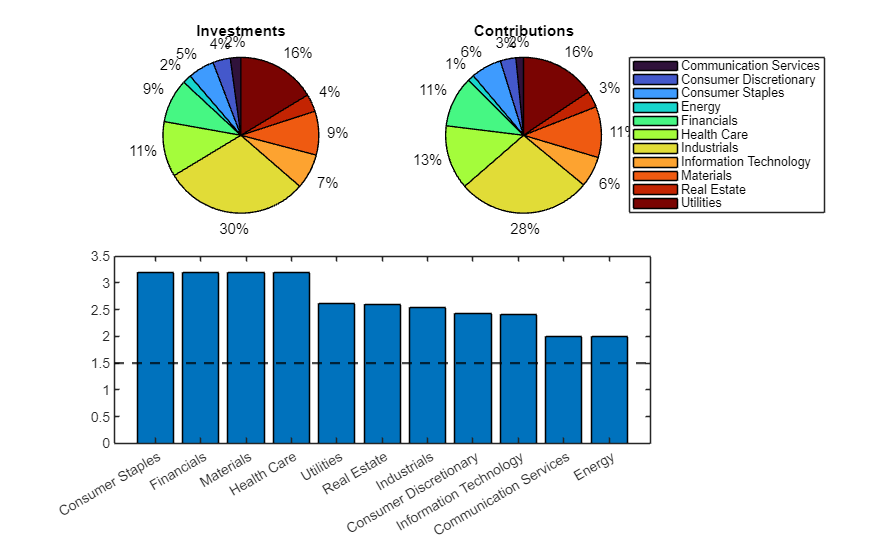

scenario_contributions = SBTi.utils.collect_company_contributions(scenario_aggregated, scenario_scores, analysis_parameters);

scenario_aggregated;
scenario_contributions;
analysis_parameters;
SBTi.utils.plot_grouped_statistics(scenario_aggregated, scenario_contributions, analysis_parameters)

scenario_contributions.temperature_score_change = scenario_contributions.temperature_score - company_contributions.temperature_score;
scenario_contributions.contribution_change = scenario_contributions.contribution - company_contributions.contribution;
largest_reductions = scenario_contributions(scenario_contributions.temperature_score_change ~= 0.0,:);